clc; clear; 
h2 = load("h2_design.mat");
hinf = load('hinf_design.mat');

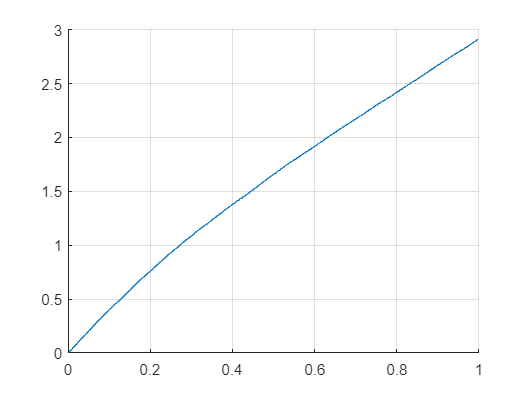

d2r = pi/180;
A = h2.Aclp;
B = [h2.Bd h2.Bu];
B = [B; zeros(3,4)];
Cz = [1/(5*d2r) 0; 0 1/10]*[1 0 -1 0; 0 1 0 0];
C = [Cz zeros(2,3)];
sys = ss(A,B,C,[]);

T = 0:0.01:1;
N = length(T);
dalpha = (rand(N,1)-0.5)*2;
dalpha_bar = dalpha/(trapz(T,dalpha.^2))^0.5;
Wa = diag(h2.kappa.^-0.5);
wa = rand(N,3);
wa_bar = wa/(trapz(T,(wa.^2)*[1;1;1])^0.5);
u = [0.01*dalpha_bar wa_bar*Wa]; 
X0 = [5.95*d2r; 900; 5.95*d2r; 7.65*d2r;0;0;0];
sol_h2 = lsim(sys,u,T,X0);
figure
grid on
hold on
plot(T,sol_h2(:,1))

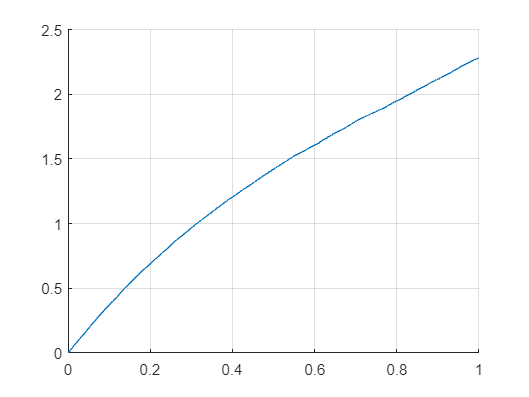

A = hinf.Aclp;
B = [hinf.Bd h2.Bu];
B = [B; zeros(3,4)];
Cz = [1 0 -1 0; 0 1 0 0];
C = [Cz zeros(2,3)];
sys = ss(A,B,C,[]);

T = 0:0.01:1;
N = length(T);
dalpha = (rand(N,1)-0.5)*2;
dalpha_bar = dalpha/(trapz(T,dalpha.^2))^0.5;
Wa = diag(h2.kappa.^-0.5);
wa = rand(N,3);
wa_bar = wa/(trapz(T,(wa.^2)*[1;1;1])^0.5);

d2r = pi/180;
u = [0.01*dalpha_bar wa_bar*Wa]; 
X0 = [5.95*d2r; 900; 5.95*d2r; 0*d2r;0;0;0];
sol_hinf = lsim(sys,u,T,X0);
Wz = [1/(5*d2r) 0; 0 1/10];
sol_hinf = sol_hinf*Wz;
figure
grid on
hold on
plot(T,sol_hinf(:,1))